# 3.4 Cubic Splines

## CP1a

Find the equations and plot the natural cubic spline that interpolates the data points

(a) (0,3),(1,5),(2,4),(3,1)

Comparing against example code from the book.

x = [0 1 2 3]';
y = [3 5 4 1]';
coeff = mysplinecoeff(x,y,"Natural")

coeff =     2.6667         0   -0.6667
    0.6667   -2.0000    0.3333
   -2.3333   -1.0000    0.3333


bookcoeff = naturalsplinecoeff(x,y)

bookcoeff =     2.6667         0   -0.6667
    0.6667   -2.0000    0.3333
   -2.3333   -1.0000    0.3333


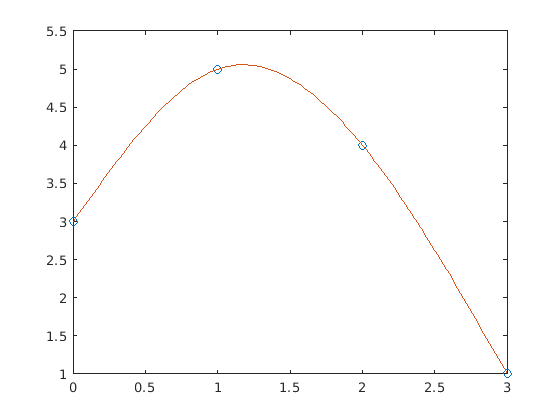

mysplineplot(x,y,coeff,50)

## CP2a

Same data points as above.

coeff = mysplinecoeff(x, y, "Not-a-knot")

coeff =     3.8333   -2.0000    0.1667
    0.3333   -1.5000    0.1667
   -2.1667   -1.0000    0.1667


bookcoeff = notaknotsplinecoeff(x,y)

bookcoeff =     3.8333   -2.0000    0.1667
    0.3333   -1.5000    0.1667
   -2.1667   -1.0000    0.1667


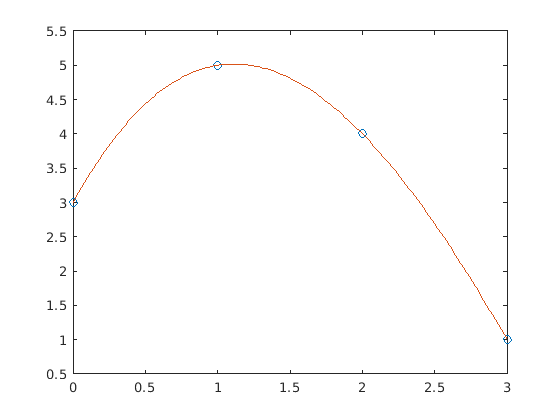

mysplineplot(x,y,coeff,50)

Yeah, I don't see *that* much of a difference between those two graphs.

The not-a-knot version does look a bit fatter, though.

function coeff=mysplinecoeff(x,y,mode)
% MYSPLINECOEFF yes it's my code haha
%               made with a great deal of
%               matlab pain (TM)

% hmmm yeah that's a better way to get *one* dimension
% than the [n, ~] = size(x) bullshit I've done.
n=length(x);

% Create del and delta vectors
del   = zeros(n-1,1);
delta = zeros(n-1,1);
for i=1:n-1
    del(i)   = x(i+1) - x(i);
    delta(i) = y(i+1) - y(i);
end

% create modified del vectors for diagonals
% with zeros in top&bottom rows
del1 = [0; del(1:n-2); 0];
del2 = [0; del(2:n-1); 0];
mid = 2*del1 + 2*del2;
% modify del1 and del2 again
% to fix whatever problem spdiags had...
del1 = [del1(2:n); 0];
del2 = [0; del2(1:n-1)];

% Create sparse matrix A
A = spdiags([del1, mid, del2], [-1,0,1], n, n);

% Set specifics of A based on end condition
if mode == "Natural"
    A(1,1) = 1;
    A(n,n) = 1;
elseif mode == "Not-a-knot"
    A(1,1:3) = [del(2), -(del(1) + del(2)), del(1)];
    A(n,n-2:n) = [del(n-1), -(del(n-2) + del(n-1)), del(n-2)];
else
    disp('yeah ok idk what you want')
end

% Create right-hand-side-vector
r = [0; 3*((delta(2:n-1) ./ del(2:n-1)) - (delta(1:n-2) ./ del(1:n-2))); 0;];
% Solve 3.24 or its variants
c = A\r;

% find b and d
d = zeros(n-1,1);
b = zeros(n-1,1);
for i=1:n-1
    d(i) = (c(i+1) - c(i)) / (3*del(i));
    b(i) = (delta(i)/del(i)) - (del(i)/3) * (2*c(i) + c(i+1));
end
coeff = [b c(1:n-1) d];
end

function mysplineplot(x,y,coeff,m)
n=length(x);
rang = (x(1):1/m:x(4))';
for i=1:n-1 % coeff rows
    for j=(i-1)*m+1:i*m+1
        % prepend y(i) to coefficient row!
        graph(j) = nest(3,[y(i) coeff(i,:)]',rang(j),repelem(x(i),3));
    end
end
plot(x,y,'o',rang,graph)
end

% BOOOOOOK....

function coeff=naturalsplinecoeff(x,y)
% from book
n=length(x);v1=0;vn=0;
A=zeros(n,n); % matrix A is nxn
r=zeros(n,1);
for i=1:n-1 % define the deltas
    dx(i)= x(i+1)-x(i);
    dy(i)=y(i+1)-y(i);
end
for i=2:n-1 % load the A matrix
    A(i,i-1:i+1)=[dx(i-1) 2*(dx(i-1)+dx(i)) dx(i)];
    r(i)=3*(dy(i)/dx(i)-dy(i-1)/dx(i-1)); % right-hand side
end

% Set endpoint conditions
% Use only one of following 5 pairs:
A(1,1) = 1; % natural spline conditions
A(n,n) = 1;
%A(1,1)=2;r(1)=v1; % curvature-adj conditions
%A(n,n)=2;r(n)=vn;
%A(1,1:2)=[2*dx(1) dx(1)];r(1)=3*(dy(1)/dx(1)-v1); %clamped
%A(n,n-1:n)=[dx(n-1) 2*dx(n-1)];r(n)=3*(vn-dy(n-1)/dx(n-1));
%A(1,1:2)=[1 -1]; % parabol-term conditions, for n>=3
%A(n,n-1:n)=[1 -1];
%A(1,1:3)=[dx(2) -(dx(1)+dx(2)) dx(1)]; % not-a-knot, for n>=4
%A(n,n-2:n)=[dx(n-1) -(dx(n-2)+dx(n-1)) dx(n-2)];
coeff=zeros(n,3);
coeff(:,2)=A\r;
% solve for c coefficients
for i=1:n-1 % solve for b and d
coeff(i,3)=(coeff(i+1,2)-coeff(i,2))/(3*dx(i));
coeff(i,1)=dy(i)/dx(i)-dx(i)*(2*coeff(i,2)+coeff(i+1,2))/3;
end
coeff=coeff(1:n-1,1:3);
end

function coeff=notaknotsplinecoeff(x,y)
% from book
n=length(x);v1=0;vn=0;
A=zeros(n,n); % matrix A is nxn
r=zeros(n,1);
for i=1:n-1 % define the deltas
    dx(i)= x(i+1)-x(i);
    dy(i)=y(i+1)-y(i);
end
for i=2:n-1 % load the A matrix
    A(i,i-1:i+1)=[dx(i-1) 2*(dx(i-1)+dx(i)) dx(i)];
    r(i)=3*(dy(i)/dx(i)-dy(i-1)/dx(i-1)); % right-hand side
end

% Set endpoint conditions
A(1,1:3)=[dx(2) -(dx(1)+dx(2)) dx(1)]; % not-a-knot, for n>=4
A(n,n-2:n)=[dx(n-1) -(dx(n-2)+dx(n-1)) dx(n-2)];
coeff=zeros(n,3);
coeff(:,2)=A\r;
% solve for c coefficients
for i=1:n-1 % solve for b and d
coeff(i,3)=(coeff(i+1,2)-coeff(i,2))/(3*dx(i));
coeff(i,1)=dy(i)/dx(i)-dx(i)*(2*coeff(i,2)+coeff(i+1,2))/3;
end
coeff=coeff(1:n-1,1:3);
end

% plot thing from book too
% modified to take coeffs in!
% ...wait, does it *seriously* not use nest?
% yeah, I'm writing this myself, thank you very much.
function [x1,y1]=splineplot(x,y,coeff,k)
n=length(x);
x1=[]; y1=[];
for i=1:n-1
    xs=linspace(x(i),x(i+1),k+1);
    dx=xs-x(i);
    ys=coeff(i,3)*dx; % evaluate using nested multiplication
    ys=(ys+coeff(i,2)).*dx;
    ys=(ys+coeff(i,1)).*dx+y(i);
    x1=[x1; xs(1:k)'];
    y1=[y1;ys(1:k)'];
end
x1=[x1; x(end)];y1=[y1;y(end)];
plot(x,y,'o',x1,y1)
end
% (which means, this function is *not* used...)